disp('============IDENTIFICAÇÃO CONVERSOR BUCK (bancada)============');

============IDENTIFICAÇÃO CONVERSOR BUCK (bancada)============


disp('Dados ensaio: 20KHz ; Ts = 50us');

Dados ensaio: 20KHz ; Ts = 50us


disp('Laboratorio LINCE');

Laboratorio LINCE


disp('Discente: Luiz Felipe Souza de Lima Silva');

Discente: Luiz Felipe Souza de Lima Silva


1. Inicialização e declaração de parametros:

clear, clc, close all
dados_csv = readmatrix('Dadosensaio_prbs500us.csv');

Nd = 500;
Ts = 5.0e-5; 

disp('------------------------------------------------------');

------------------------------------------------------


disp('PARAMETROS DE PROJETO:');

PARAMETROS DE PROJETO:



Fs = 20000

Fs = 20000

d =  0.3

d = 0.3000

Vs = 30

Vs = 30

Cp = 0.000041666667

Cp = 4.1667e-05

L = 0.000470

L = 4.7000e-04

R = 10.0

R = 10

num = Vs/(Cp*L);
den = [1,1/(Cp*R) , 1/(Cp*L)];

2. Função de transferencia matematica:

disp('------------------------------------------------------');

------------------------------------------------------


disp('FUNÇÃO DE TRANSFERENCIA MODELADA ANALITICAMENTE:');

FUNÇÃO DE TRANSFERENCIA MODELADA ANALITICAMENTE:



Gs = tf(num,den)

Gs =
 
         1.532e09
  -----------------------
  s^2 + 2400 s + 5.106e07
 
Continuous-time transfer function.
Model Properties



disp('Polos e zeros:');

Polos e zeros:



pole(Gs)

ans = 1.0e+03 *

  -1.2000 + 7.0444i
  -1.2000 - 7.0444i



disp('Resposta ao Degrau:');

Resposta ao Degrau:


figure(1)
clf;
step(Gs)
xlabel('t'); ylabel('V(t)');
grid on; legend('Location', 'best');
title('Resposta ao Degrau G(s)') 
exportgraphics(gcf, 'resposta_degrau.png', 'Resolution', 300);


disp('Discretização de G(s) utilizando método "matched":');

Discretização de G(s) utilizando método "matched":


Gz = c2d(Gs, Ts ,'zoh')

Gz =
 
     1.821 z + 1.749
  ----------------------
  z^2 - 1.768 z + 0.8869
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


3. Coleta de dados e Identificação:

disp('COLETA DE DADOS E IDENTIFICAÇÃO:');

COLETA DE DADOS E IDENTIFICAÇÃO:


t = dados_csv(1:end-Nd, 1)'; %tempo
u = dados_csv(Nd:end-1, 2)'; %PRBS
v = dados_csv(Nd:end-1, 3)'; %Saída

mu_u = mean(u);
mu_v = mean(v);
u = u - mu_u;
v = v - mu_v;

y = transpose(v); 

disp('OBS.:Entrada num conjunto de 200 amostras.');

OBS.:Entrada num conjunto de 200 amostras.


figure(2);
clf; 
subplot(2,1,1);
stairs(1:length(u), u, 'LineWidth', 1.4);
ylabel('Entrada PRBS (u)');
title('Ensaio de Identificação - Conversor Buck');
xlim([0 1000]);   
ylim([-0.08 0.08]); 
grid on;

subplot(2,1,2);
plot(t(1:length(v)), v, 'LineWidth', 1.4);
ylabel('Saída Real (v)');
xlabel('Tempo (s)');
grid on;



%% Construção matricial - regressores
Ns = numel(t);

M = zeros(Ns-3,4);

for n = 3:Ns
    phi = [y(n-1), y(n-2), u(n-1), u(n-2)];
    M(n, :) = phi;
end

theta = M\y;
a1 = theta(1);
a2 = theta(2);
b1 = theta(3);
b2 = theta(4);
ys = zeros(size(y));
ys(1:2) = y(1:2);

yp = M * theta;

disp('MODELO ARX OBTIDO:');

MODELO ARX OBTIDO:


Be = [0, b1, b2];
Ae = [1, -a1, -a2]; 
Gze = tf(Be, Ae, Ts)

Gze =
 
    0.09151 z + 0.5443
  ----------------------
  z^2 - 1.847 z + 0.8815
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


4. Analise e comparação de modelos:

disp('ANALISE E COMPARAÇÃO DE MODELOS:');

ANALISE E COMPARAÇÃO DE MODELOS:


figure(3);
clf; 
plot(t, y, 'b', 'LineWidth', 1.5)
hold on

plot(t, yp, 'r--', 'LineWidth', 1.5)

legend('Saída do sistema real', 'ARX', 'Location', 'best');
hold off
grid on
xlabel('Tempo (s)');
ylabel('V(t)');
title('ARX VS saída do sistema real');
xlim([0 0.05]);    %maximo de 50us
ylim([-1.5 2]); 


disp('Funções de transferencia:');

Funções de transferencia:


disp('Gz modelo analitico');

Gz modelo analitico


Gz

Gz =
 
     1.821 z + 1.749
  ----------------------
  z^2 - 1.768 z + 0.8869
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties



disp('Gze modelo estimado');

Gze modelo estimado



Gze

Gze =
 
    0.09151 z + 0.5443
  ----------------------
  z^2 - 1.847 z + 0.8815
 
Sample time: 5e-05 seconds
Discrete-time transfer function.
Model Properties


disp('------------------------------------------------------');

------------------------------------------------------


5.Ajuste R2:

disp('AJUSTE R2:');

AJUSTE R2:


R2 = 1 - sum((y - yp).^2)/sum((y - mean(y)).^2)

R2 = 0.9989

disp('------------------------------------------------------');

------------------------------------------------------


6. Cálculo do erro de predição/resíduo:

disp('Cálculo do erro de predição/resíduo:');

Cálculo do erro de predição/resíduo:


e = y - yp;

figure(6);
clf;
plot(e, 'b', 'LineWidth', 1.2);
grid on;
title('Resíduos / Erro de Predição e(t)');
xlabel('Amostras (k)');
ylabel('Erro [V]');

disp('------------------------------------------------------');

------------------------------------------------------


7. Analise de polos e zeros:

disp('ANALISE DE POLOS E ZEROS:');

ANALISE DE POLOS E ZEROS:



disp('BLUE - GZ');

BLUE - GZ


disp('RED - GZe');

RED - GZe


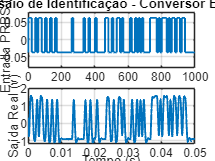


figure(7)
clf;
pzmap(Gz)
zgrid
hold on

pzmap(Gze)
hold off

xlabel('Eixo real');
ylabel('Eixo imaginario');
title('Mapa de polos e zeros');

disp('------------------------------------------------------');

------------------------------------------------------


8. Resposta ao degrau:

disp('resposta ao degrau Modelo discreto analitico');

resposta ao degrau Modelo discreto analitico


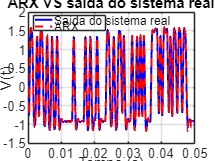


Ganho_Gz = dcgain(Gz);
Ganho_Gze = dcgain(Gze);
K_corr = Ganho_Gz / Ganho_Gze; 
Gze = Gze * K_corr;

figure(6)
clf;
step(Gz, Gze)
xlabel('t'); ylabel('v(t)');
grid on; 
legend('Gz', 'Gze', 'Location', 'best');
title('Resposta ao Degrau Gz e Gze');

disp('------------------------------------------------------');

------------------------------------------------------


9. Diagrama de Bode:

figure(7);
disp('Diagrama de Bode:');

Diagrama de Bode:


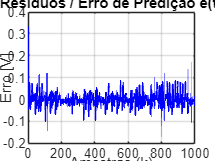

clf;
bode(Gz, 'b', Gze, 'r--');
grid on;
legend('Gz (Analítico)', 'Gze (Estimado ARX)', 'Location', 'best');
title('Diagrama de Bode: Gz vs Gze');

disp('------------------------------------------------------');

------------------------------------------------------


10. Projeto Controlador PI (discreto)

disp('Projeto controlador PI - discreto (Forward Euler)');

Projeto controlador PI - discreto (Forward Euler)


Gze_proj = tf(Be, Ae, Ts);

%C(z) = Kp + Ki*Ts/(z-1)
Kp = 0.005;   
Ki = 30;     

C_s = pid(Kp, Ki);
C   = c2d(C_s, Ts, 'zoh')

C =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 0.005, Ki = 30, Ts = 5e-05
 
Sample time: 5e-05 seconds
Discrete-time PI controller in parallel form.
Model Properties



M_aberta = C*Gze_proj;
M_fechada = feedback(M_aberta, 1);

[Gm, Pm, ~, Wcp] = margin(M_aberta);
disp(['Margem de ganho  = ' num2str(20*log10(Gm),'%.1f') ' dB']);

Margem de ganho  = 14.5 dB


disp(['Margem de fase   = ' num2str(Pm,'%.1f') ' graus']);

Margem de fase   = 87.5 graus


disp(['Freq. de cruzamento = ' num2str(Wcp,'%.0f') ' rad/s (' num2str(Wcp/(2*pi),'%.0f') ' Hz)']);

Freq. de cruzamento = 566 rad/s (90 Hz)


disp(['Polos de malha fechada (|z|): ' num2str(abs(pole(M_fechada))','%.3f ')]);

Polos de malha fechada (|z|): 0.972 0.953 0.953


disp('------------------------------------------------------');

------------------------------------------------------


disp('Ganhos do controlador:');

Ganhos do controlador:


gainP = Kp

gainP = 0.0050

gainI = Ki

gainI = 30

disp('Função de transferencia controlador:');

Função de transferencia controlador:



Gc = zpk(C)

Gc =
 
  0.005 (z-0.7)
  -------------
      (z-1)
 
Sample time: 5e-05 seconds
Discrete-time zero/pole/gain model.
Model Properties



syms u(k) e(k)
disp('Equação de diferenças controlador digital:');

Equação de diferenças controlador digital:



bk_1 = gainP + (gainI*Ts)

bk_1 = 0.0065

bk_2 = gainP

bk_2 = 0.0050

u_k = u(k-1) + e(k)*(bk_1) - (bk_2)*e(k-1)

$$u\_k = u\left(k-1\right)-\frac{e\left(k-1\right)}{200}+\frac{13\,e\left(k\right)}{2000}$$


disp('Resposta ao degrau unitário (nominal e robustez):');

Resposta ao degrau unitário (nominal e robustez):



figure(8); clf;
stepplot(M_fechada, feedback(C*Gze,1), feedback(C*Gz,1), 0.03);
grid on;
legend('Gze ARX (projeto)', 'Gze com K_{corr}', 'Gz analítico', 'Location', 'best');
title('Malha fechada com o PI projetado');

11. Resultados PI bancada:

dados_ccs = readmatrix('DadosPI - DadosPI.csv.csv');
disp('ANALISE E COMPARAÇÃO DOS CONTROLADORES:');

ANALISE E COMPARAÇÃO DOS CONTROLADORES:



t_real = dados_ccs(:, 1);
u_real = dados_ccs(:, 2); 
v_real = dados_ccs(:, 3); 

figure(9);
clf;
subplot(2,1,1);
plot(t_real, v_real, 'b', 'LineWidth', 1.5);
grid on;
ylabel('Tensão na Carga [V]');
title('Resposta ao Degrau em Malha Fechada (Bancada Real)');

subplot(2,1,2);
plot(t_real, u_real, 'r', 'LineWidth', 1.5);
grid on;
xlabel('Tempo [s]');
ylabel('Duty Cycle (u)');


%% 5. Simulação da Resposta Teórica com a mesma Referência do DSP
Tz_analitico = feedback(C * Gz, 1);

% O código no DSP arranca com ref = 9V, sobe para 10V na amostra 300, e desce na 900
Ns = length(t_real);
v_ref = 9.0 * ones(Ns, 1);       
v_ref(301:900) = 10.0;           

% Simula o sistema ideal com a mesma referência
[v_sim, t_sim] = lsim(Tz_analitico, v_ref, t_real);

%% 6. Plotagem da Comparação (Física vs Teórica)
figure('Name', 'Comparação Real vs Teórico', 'Position', [100 100 800 600]);

% --- Subplot 1: Tensão na Carga ---
subplot(2,1,1);
plot(t_real, v_real, 'b', 'LineWidth', 1.5); hold on;
plot(t_sim, v_sim, 'r--', 'LineWidth', 1.5);
plot(t_real, v_ref, 'k:', 'LineWidth', 1.2); 
grid on;
title('Resposta em Malha Fechada: Planta Física vs Planta Analítica Ideal');
ylabel('Tensão de Saída v(t) [V]');
legend('Bancada (Planta Física c/ atrasos e perdas)', ...
       'Simulação (Planta Ideal)', 'Referência', 'Location', 'best');
xlim([0 max(t_real)]);


Uz_analitico = feedback(C, Gz);
[u_sim, ~] = lsim(Uz_analitico, v_ref, t_real);

subplot(2,1,2);
plot(t_real, u_real, 'b', 'LineWidth', 1.5); hold on;
plot(t_sim, u_sim, 'r--', 'LineWidth', 1.5);
grid on;
ylabel('Esforço de Controlo u(t)');
xlabel('Tempo [s]');
legend('Duty Cycle Real', 'Duty Cycle Simulado', 'Location', 'best');
xlim([0 max(t_real)]);

disp('Comparação concluída e gráficos gerados!');

Comparação concluída e gráficos gerados!
